**Fast DrawingEfficient Plot Animation**

**Efficient Animation of a Sine Wave in MATLAB**

Animating a sine wave is a great way to visualize periodic motion and explore efficient plotting techniques. For this project, I animated a sine wave with a continuously increasing phase, ensuring that the process was computationally efficient and visually smooth.

I began by defining a range of x values between 0 and 2π2, divided into 100 points for smoothness. To avoid repeatedly redrawing the entire plot, I initialized a figure and predefined a `plot` object to represent the sine wave. This approach allowed me to update only the y-data of the plot during each frame of the animation, minimizing the computational load.

The animation was driven by a loop, where the phase of the sine wave (θ\thetaθ) increased incrementally from 0 to 10π. For each iteration, I calculated the updated y-values by adding the phase shift to the sine function and used MATLAB’s `set` function to efficiently update the plot’s y-data. The `drawnow` command refreshed the figure to display the changes in real time.

This method produced a seamless animation of the sine wave propagating across the x-axis. The efficiency of this approach, achieved by updating only the line data instead of redrawing the entire plot, ensured smooth performance even with 500 iterations.

This project reinforced the importance of optimizing graphics operations for animation

% Efficient Animation with Updated Line Data
% I want to animate a sine wave with increasing phase efficiently.

% Generate x values
x = linspace(0, 2 * pi, 100);

% Initialize figure
figure;

% Predefine the line object
h = plot(x, sin(x), 'b', 'LineWidth', 2);
grid on;

% Animate the sine wave
for theta = linspace(0, 10 * pi, 500)
    y = sin(x + theta); % Update y data
    set(h, 'YData', y); % Update the plot
    drawnow; % Refresh the plot
end

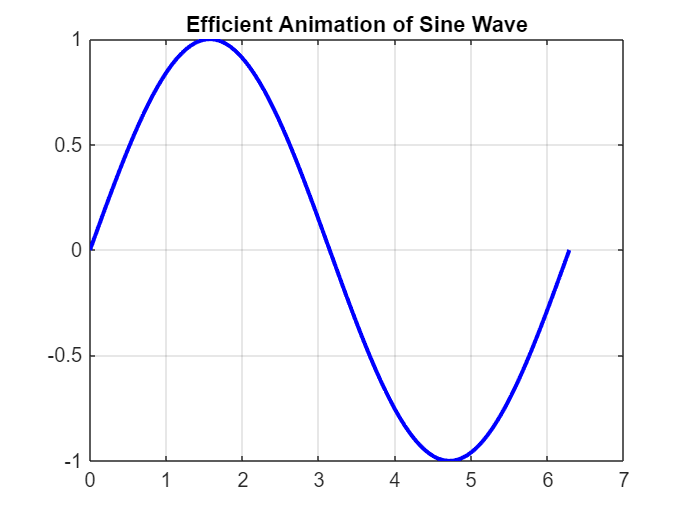

title('Efficient Animation of Sine Wave');